## Hair dryer data

*	"Laboratory setup acting like a hair dryer. Air is fanned through a tube*

*	and heated at the inlet. The air temperature is measured by a *

*	thermocouple at the output. The input is the voltage over the heating *

*	device (a mesh of resistor wires)."*

*Inputs:*

*	u: voltage of the heating device *

*Outputs:*

*	y: output air temperature *

**In this example project i'm using the data to practice system**

** identification skills. Any rights to data set belong to the author.**

The following data set is avaiable through the website below:

`https://homes.esat.kuleuven.be/~smc/daisy/daisydata.html`

*Contributed by:*

*	Favoreel KULeuven*

*	Departement Electrotechniek ESAT/SISTA, Kardinaal Mercierlaan 94 , B-3001 Leuven Belgium*

*	wouter.favoreel@esat.kuleuven.ac.be*

### **The code**

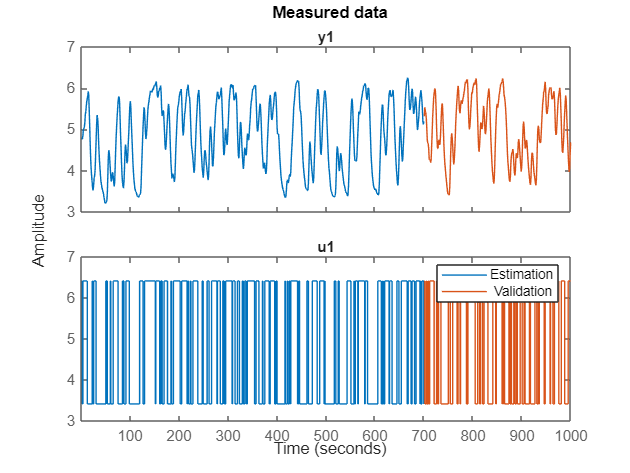

clc
clear


%%%%%%%%%%% Import data
addpath('Data')  
load ('Data\dryer.dat')

dt = 1; %%% 1 second

t= (0:1:length(dryer(:,1))-1);

x = dryer(:,1);
%dryer(:,1) = (x - min(x)) / (max(x) - min(x));

u = dryer(:,1);
y = dryer(:,2);


data_dryer = iddata(y,u,dt);


data_est = data_dryer(1:700);
data_val = data_dryer(701:1000);

%%%%%%%%%%%%% Plot the data

figure;

plot(data_est,data_val)
title('Measured data')

legend('Estimation',' Validation')

**Linear ARX orders check**

%%%%%  let's get hints what orders should be used in ARX model

V = arxstruc(data_est,data_val, struc(1:10, 1:10,1:10));
%%%% select best order by Akaike's information criterion (AIC)
nn = selstruc(V,'aic')

nn =      4     9     2


**Hammerstein-Wiener Model**

system = tfest(data_est, 4,3,NaN)


system =
 
  From input "u1" to output "y1":
                -0.06267 s^3 + 0.1309 s^2 + 7.227e-05 s - 2.345e-09
  exp(-1*s) * -------------------------------------------------------
              s^4 + 0.7056 s^3 + 0.1382 s^2 + 6.484e-05 s + 9.131e-13
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 4   Number of zeros: 3
   Number of free coefficients: 8
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                              
Estimated using TFEST on time domain data "data_est".
Fit to estimation data: 89.15%                       
FPE: 0.008891, MSE: 0.008591                         
 
Model Properties


mhw1 = nlhw(data_est, nn);

**Deep Learning nlarx model**

%%%% the following code was copied from Matlab's website

if exist('feedforwardnet','file')==2 % run only if Deep Learning Toolbox is available
    ff = feedforwardnet([5 20]);  % use a feed-forward network to map regressors to output
    ff.layers{2}.transferFcn = 'radbas';
    ff.trainParam.epochs = 100;

    ff.trainParam.showWindow = false; %%%% don't show the window to speed up computation
     %%%%%%% the DL results can be examined later

     
    % Create a neural network mapping function that wraps the feed-forward network
    OutputFcn = idFeedforwardNetwork(ff);
    
    model_dl1 = nlarx(data_est,nn, OutputFcn);

end

**Machine Learning Toolbox - nlarxmodel**


mp1 =

Nonlinear ARX model with 1 output and 1 input
  Inputs: u1
  Outputs: y1

Regressors:
  Linear regressors in variables y1, u1
  List of all regressors

Output function: Gaussian process function using a Matern32 kernel
Sample time: 1 seconds

Status:                                              
Estimated using NLARX on time domain data "data_est".
Fit to estimation data: 95.76% (prediction focus)    
FPE: 0.001392, MSE: 0.00131                          




mp2 =

Nonlinear ARX model with 1 output and 1 input
  Inputs: u1
  Outputs: y1

Regressors:
  Linear regressors in variables u1
  List of all regressors

Output function: Bagged Regression Tree Ensemble
Sample time: 1 seconds

Status:                                              
Estimated using NLARX on time domain data "data_est".
Fit to estimation data: 93.4%                        
MSE: 0.003178                                        



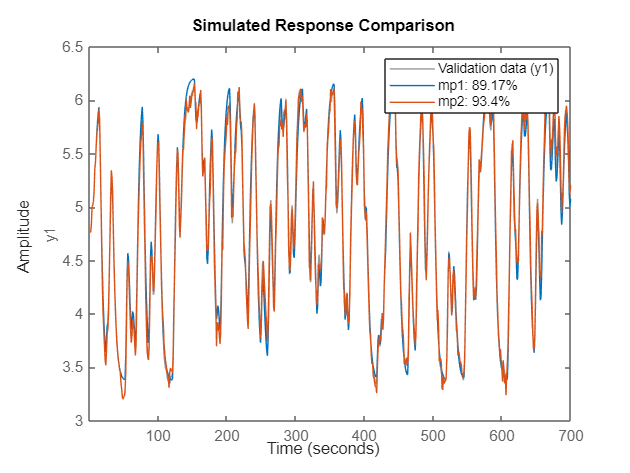

if exist('fitrgp','file')==2
    Warn = warning('off','stats:lasso:MaxIterReached');
    mp1 = nlarx(data_est, nn, idGaussianProcess('Matern32'));

    % Create boosted ensemble of 200 regression trees
    En = idTreeEnsemble;
    En.EstimationOptions.FitMethod = 'lsboost-resampled';
    En.EstimationOptions.NumLearningCycles = 200;
    En.EstimationOptions.ResampleFraction = 1;
    mp2 = nlarx(data_est, [0 70 3], En);
    compare(data_est, mp1, mp2) % compare model fits to estimation data
    warning(Warn)
end

**NLARX model with Sigmoid Network and Wavelet Network**


system2= nlarx(data_est, nn, idSigmoidNetwork(8));

mc1_ini = idnlarx('y1','u1', nn, idCustomNetwork(@gaussunit));
mc1 = nlarx(data_est,mc1_ini);


## **Comparision**

figure;
compare(data_est,system, system2,mhw1,model_dl1,mc1,mp1,mp2)

Error using system
Not enough input arguments.

title('Fit to estimation data')


compare(data_val,system, system2,mhw1,model_dl1,mc1,mp1,mp2)
title('Fit to validation data')

compare(data_dryer,system,model_dl1, mhw1,mp1)



